# Merton Model incorporating a Jump Diffusion process

## Setting the starting parameters...

% Requested starting parameters
D = 95;         % Face value of debt at maturity   
sigma = 0.23;   % volatility of firm value
lambda = 1;     % jump intensity
alpha  = 0.05;    % volatility of jump when it occurs
delta  = 0.5;   % persistence
r = 0.028;      % risk-free rate
INITIAL_VAL = [75, 90, 125, 180];
arr = length(INITIAL_VAL);
T = 10;         % time periods
incr = 0.5;
maturities = T/incr;
t = linspace(incr, T, maturities)*12;
rng(1066,'twister') % randomisation seed for replication

sims = 100000;  % Number of simulations
n = 12*T;    % Number of incremental values = months

% Create matrix to save aggrgated simulated credit spreads
spreads = zeros(maturities, arr);


## Run the Looped simulation

% Loop over number of initial values
for i = 1:arr
    % Calculate firm values using our function Jump_diffusion
    FirmValues = Jump_diffusion(INITIAL_VAL(i), r, sigma, T, n, sims, lambda, alpha, delta);
    
    % Loop over maturities
    for j = 1:maturities 
        % Determine non-negative end net values for a firm
        ND = D - FirmValues(t(j)+1,:);
        Term_Val = zeros(size(ND));
        path = ND>0;                
        Term_Val(path) = ND(path);
        
        % In accordance with the Merton Model, use the terminal value of the simulation to 
        % calculate the price of a European put, and the subsequent Debt Value
        Euro_Put = mean(Term_Val)*exp(-r*(j/2));
        B = D*exp(-r*(j/2)) - Euro_Put;        
        % Credit Spread = Bond yield - Risk-free rate
        y = log(D/B)/(j/2);
        spreads(j,i) = (y - r)*10000;
    end
end


## Plot individual simulation

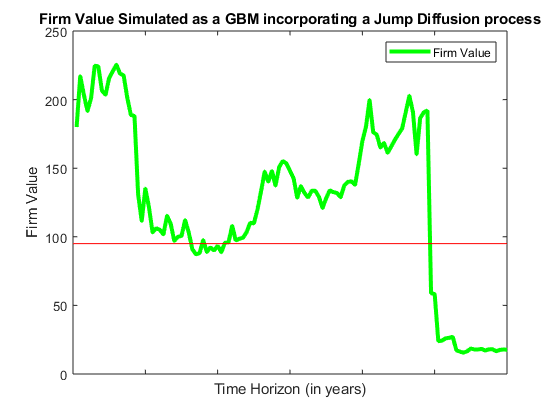

%Choose a random jump simulation (any number between 1- 100,000)...
Jump_sim = FirmValues(:,30133);
plot(Jump_sim,'g','LineWidth', 3);
hline = refline([0 D]);    % Face Value of Debt is our Default line
hline.Color = 'r';
xlim([0 120]);
set(gca,'XTickLabel',[]);
legend('Firm Value','Location', 'NorthEast')
title('Firm Value Simulated as a GBM incorporating a Jump Diffusion process')
xlabel('Time Horizon (in years)')
ylabel('Firm Value')

## Plot aggregated Credit spreads vs Time Horizon

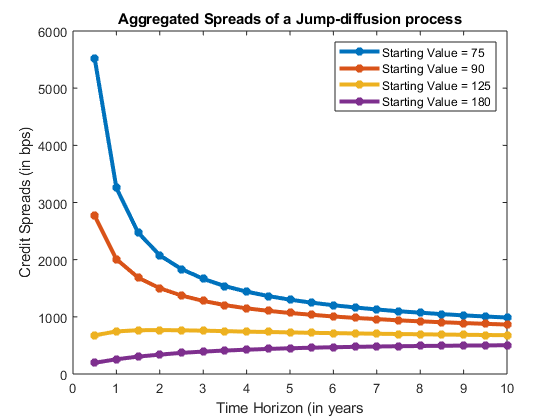

credit_spreads = figure();
T_Horizon = linspace(incr, T, maturities);
plot(T_Horizon,spreads,'-*','LineWidth', 3)
legend('Starting Value = 75', 'Starting Value = 90', 'Starting Value = 125', 'Starting Value = 180','Location', 'NorthEast')
title('Aggregated Spreads of a Jump-diffusion process')
xlabel('Time Horizon (in years')
ylabel('Credit Spreads (in bps)')

## Jump Function

function Firm_Value = Jump_diffusion(INITIAL_VAL, mu, sigma, T, n, sims, lambda, alpha, delta)
    
    % Create an empty matrix to hold simulations with incremental time steps
    % Simulations here are Poisson distributed generated RV's with mean parameter lambda

    Firm_Value = zeros(n+1,sims);
    incr = T/n;
    Firm_Value(1,:) = INITIAL_VAL;    
    matrix = randn(n,sims);     
    poisson_matrix = poissrnd(lambda*incr, sims,n);
    
    % Now Loop through time...
    for i = 1:n
        main = max(poisson_matrix(:,i));    % obtain largest simulation "jump" and collate in an empty matrix
        jumps = zeros(main, sims);           
        
        % Calculate the jump part of the evolution of the firm value
        if main > 0
            % Loop over the maximum number of jumps among the simulations
            for j = 1:main
                % Draw the jumps size
                temp = normrnd(alpha-0.5*delta^2, delta^2, 1, sims);
                
                % Add the jumps to the simulated paths that had jump(s) in
                % the period
                path = poisson_matrix(:,i) >= j;
                jumps(j,path) = temp(path);
            end
        end
        
        % Firm value then evolves with the change
        Val_increment = Firm_Value(i,:)*mu*incr + Firm_Value(i,:)*sigma*sqrt(incr).*matrix(i,:)+ Firm_Value(i,:).*sum(jumps,1);
        Firm_Value(i+1,:) = Firm_Value(i,:) + Val_increment; 
        % ...where there is a non-negative firm-value limit
        limit = Firm_Value(i+1,:) < 0;
        Firm_Value(i+1,limit) = 0;
    end
end